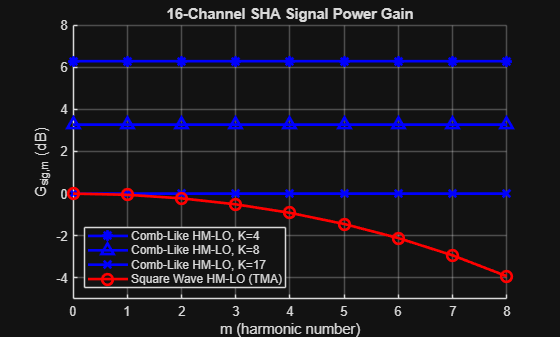

%% Reproduce Paper Fig. 7(a) - Signal Power Gain vs Harmonic Number
N = 16;
P_LO = 17 / (N^2); % Normalized so that Gsig,comb = 0dB for K = 17
K_values = [4, 8, 17];
m_plot = 0:8;
figure;
hold on;
markers = {'*', '^', 'x'};
labels = {'Comb-Like HM-LO, K=4', 'Comb-Like HM-LO, K=8', 'Comb-Like HM-LO, K=17'};
% Plot comb LO lines first
for k_idx = 1:length(K_values)
   K = K_values(k_idx);
   beta_comb = sqrt(P_LO / K);
   G_comb = 10*log10(N^2 * beta_comb^2) * ones(size(m_plot));
   plot(m_plot, G_comb, ['b' markers{k_idx} '-'], ...
       'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', labels{k_idx});
end
% Plot square wave TMA
G_sq = zeros(size(m_plot));
for idx = 1:length(m_plot)
   m = m_plot(idx);
   if m == 0
       beta_sq = 1/N;
   else
       beta_sq = abs(sin(pi*m/N) / (pi*m));
   end
   G_sq(idx) = 10*log10(N^2 * beta_sq^2 + eps);
end
plot(m_plot, G_sq, 'ro-', 'LineWidth', 2, 'MarkerSize', 8, ...
   'DisplayName', 'Square Wave HM-LO (TMA)');
xlabel('m (harmonic number)');
ylabel('G_{sig,m} (dB)');
title('16-Channel SHA Signal Power Gain');
legend('Location', 'southwest');
grid on;
ylim([-5 8]);
xlim([0 8]);

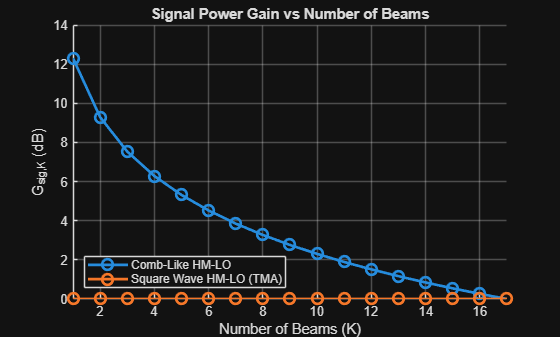

drawnow;
%% Reproduce Paper Fig. 7(b) - Signal Power Gain vs Number of Beams
k_beams = 1:17;
G_comb = zeros(size(k_beams));
G_square = zeros(size(k_beams));
for i = 1:length(k_beams)
   K = k_beams(i);
   beta_comb = sqrt(P_LO / K);
   beta_square = 1 / N;
   G_comb(i) = 10*log10(N^2 * beta_comb^2);
   G_square(i) = 10*log10(N^2 * beta_square^2);
end
figure;
hold on;
plot(k_beams, G_comb, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Comb-Like HM-LO');
plot(k_beams, G_square, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Square Wave HM-LO (TMA)');
xlabel('Number of Beams (K)');
ylabel('G_{sig,K} (dB)');
title('Signal Power Gain vs Number of Beams');
legend('Location', 'southwest');
grid on;
ylim([0 14]);
xlim([1 17]);

drawnow;



